% importing data
df1 = readtable("https://docs.google.com/spreadsheets/d/e/2PACX-1vQgTBH8O8poeZfj9jzisyRf7N_LQ4I4pW6F1-crvknL2diNhYowfQI-BnnuvBbyuJh1FurJZ_X3Q5_5/pub?gid=999031192&single=true&output=csv")

df1 = 1×5 table
          description          value     uom      uncertainty       tool    
    _______________________    _____    ______    ___________    ___________

    {'lunghezza fenditura'}    1.85     {'cm'}       0.005       {'calibro'}


df2 = readtable("https://docs.google.com/spreadsheets/d/e/2PACX-1vQgTBH8O8poeZfj9jzisyRf7N_LQ4I4pW6F1-crvknL2diNhYowfQI-BnnuvBbyuJh1FurJZ_X3Q5_5/pub?gid=0&single=true&output=csv")

df2 = 10×15 table
    configuration    measure_id    x_proiettore    x_oggetto    x_lente    x_schermo_inf    x_schermo_sup    x_uncertainty     x_uom       x_tool      l_img_inf    l_img_sup    l_uncertainty     l_uom       l_tool   
    _____________    __________    ____________    _________    _______    _____________    _____________    _____________    _______    __________    _________    _________    _____________    _______    ___________

          1          {'C1M1' }       

df3 = readtable("https://docs.google.com/spreadsheets/d/e/2PACX-1vQgTBH8O8poeZfj9jzisyRf7N_LQ4I4pW6F1-crvknL2diNhYowfQI-BnnuvBbyuJh1FurJZ_X3Q5_5/pub?gid=905714583&single=true&output=csv")

df3 = 1×13 table
    configuration    measure_id    x_proiettore    x_oggetto    x_lente    x_schermo    x_uncertainty     x_uom       x_tool      l_img    l_uncertainty     l_uom       l_tool   
    _____________    __________    ____________    _________    _______    _________    _____________    _______    __________    _____    _____________    _______    ___________

          2           {'C2M1'}         4.6           10.1        31.15       50.4           0.05         {'CMT'}    {'regolo'}    1.85         0.005        {'CMT'}    {'calibro'}


df4 = readtable("https://docs.google.com/spreadsheets/d/e/2PACX-1vQgTBH8O8poeZfj9jzisyRf7N_LQ4I4pW6F1-crvknL2diNhYowfQI-BnnuvBbyuJh1FurJZ_X3Q5_5/pub?gid=245849005&single=true&output=csv")

df4 = 11×13 table
    configuration    measure_id    x_oggetto    x_schermo    x_medio    x_lente_1    x_lente_2    x_uncertainty      uom         tool        s       d      delta
    _____________    __________    _________    _________    _______    _________    _________    _____________    _______    __________    ____    ____    _____

          2          {'C2M1' }       10.1           54        32.05       24.15         38.9          0.05         {'CMT'}    {'regolo'}     7.9    6.85    1.05 
          2          {'C2M2' }       10.1         54.

% assegno lunghezza oggetto
o = df1.value

o = 1.8500


% calcolo p: distanza oggetto-lente
p = abs(df2.x_lente-df2.x_oggetto)

p =    11.7000
   12.4000
   12.9000
   13.4000
   13.9000
   14.4000
   14.7000
   14.9000
   15.2000
   15.4000


df2.p = p;

% calcolo q: distanza lente-immagine
q_inf = abs(df2.x_lente - df2.x_schermo_inf)

q_inf =    44.5000
   37.9000
   36.9000
   33.3500
   31.3000
   29.2000
   28.0500
   27.8000
   26.6000
   26.1000


q_sup = abs(df2.x_lente - df2.x_schermo_sup)

q_sup =    56.6000
   43.4000
   41.9000
   35.4000
   32.8000
   29.8000
   29.7000
   28.8000
   27.7000
   27.3000


q = (q_inf+q_sup)/2

q =    50.5500
   40.6500
   39.4000
   34.3750
   32.0500
   29.5000
   28.8750
   28.3000
   27.1500
   26.7000


% l'incertezza sulla posizione dello schermo è data dal semi-intervallo entro il quale l'immagine appare ugualmente nitida
dq = abs(df2.x_schermo_sup - df2.x_schermo_inf)/2

dq =     6.0500
    2.7500
    2.5000
    1.0250
    0.7500
    0.3000
    0.8250
    0.5000
    0.5500
    0.6000


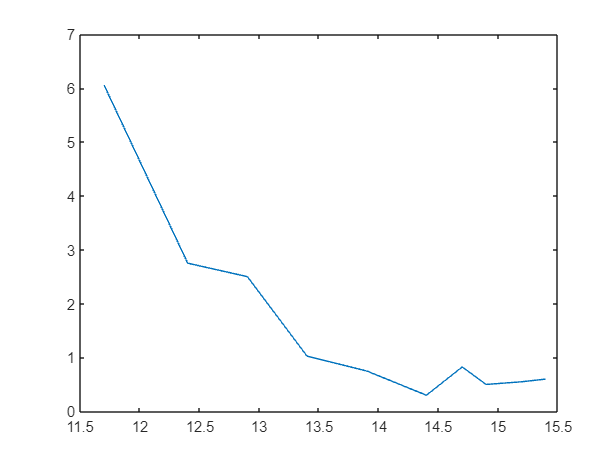

plot(p,dq)

noto che il l'ampiezza del semi intervallo diminuisce all'aumentare di p distanza oggetto lente

df2.q = q;
df2.dq = dq;

% calcolo f mediante formula (2) scheda
f = (p.*q)./(p+q)

f =     9.5010
    9.5016
    9.7182
    9.6415
    9.6952
    9.6765
    9.7410
    9.7609
    9.7445
    9.7667


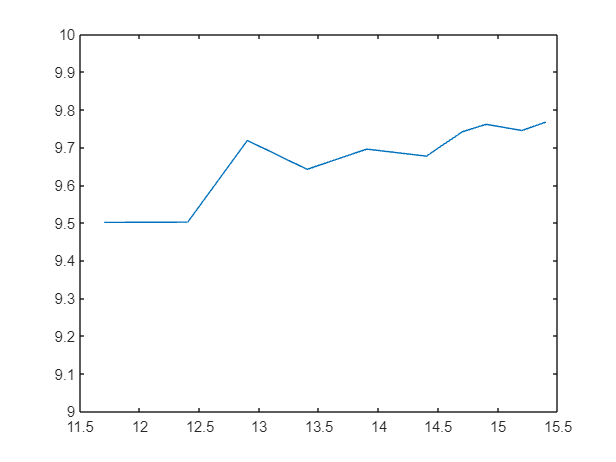

plot(p,f)
ylim([9 10])

% fare: propagazione errore su f
% fare: media di f

% fare: bestfit per determinare f
% fare:  Confrontare il valore di m dato dal rapporto q/p con il valore dedotto dalla misura diretta di i e o.

% functions



